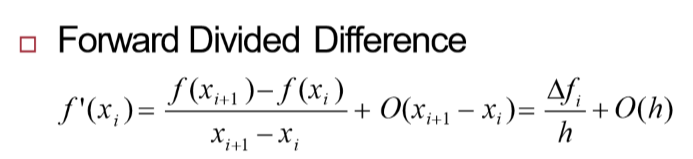

x_i = 0.5;

stepSize = 0.5;
target = 1;

for h= x_i:stepSize:target
    x_i1 = x_i + h;
    
    f_x = -0.1*(x_i^4)- 0.15*(x_i^3) - 0.5*(x_i^2) - 0.25*x_i + 1.2;
    f_xi = -0.1*(x_i1^4)- 0.15*(x_i1^3) - 0.5*(x_i1^2) - 0.25*x_i1 + 1.2;
    
    f1_xi = (f_xi - f_x)/(x_i1 - x_i);
    
    fprintf('I = %f \t f1_xi =  %f \n', h,f1_xi)
end

I = 0.500000 	 f1_xi =  -1.450000 
I = 1.000000 	 f1_xi =  -2.237500 


%Error
% 

## Find Root

### Bracketing Method

#### Bisection Method

clear
clc

x_l = 0.1;
x_u = 2;

x_r = (x_l + x_u)/2;

epsilon_a = 1E-10;

#### False Position Method

#### 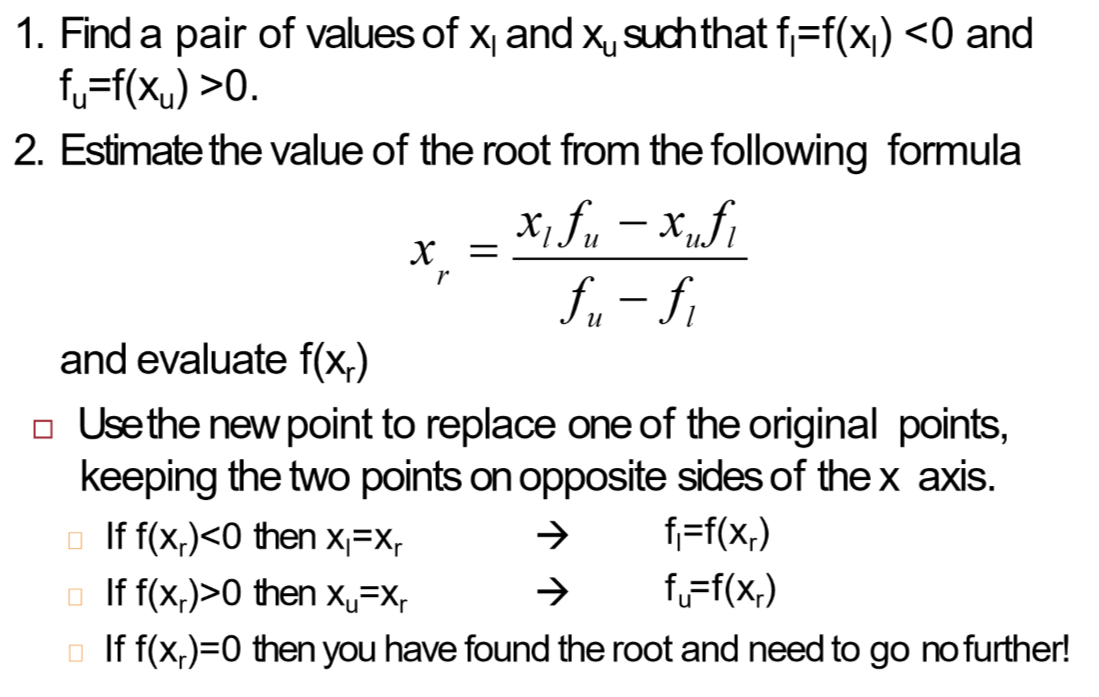

clear
clc

Example 1

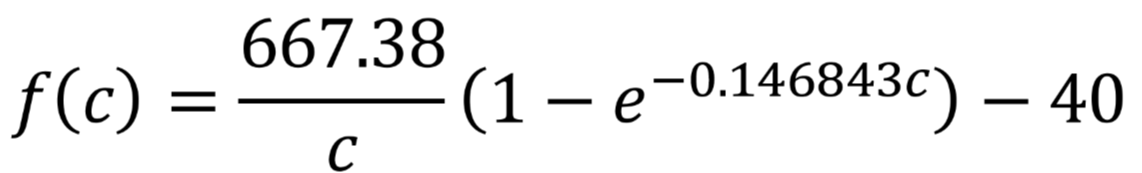

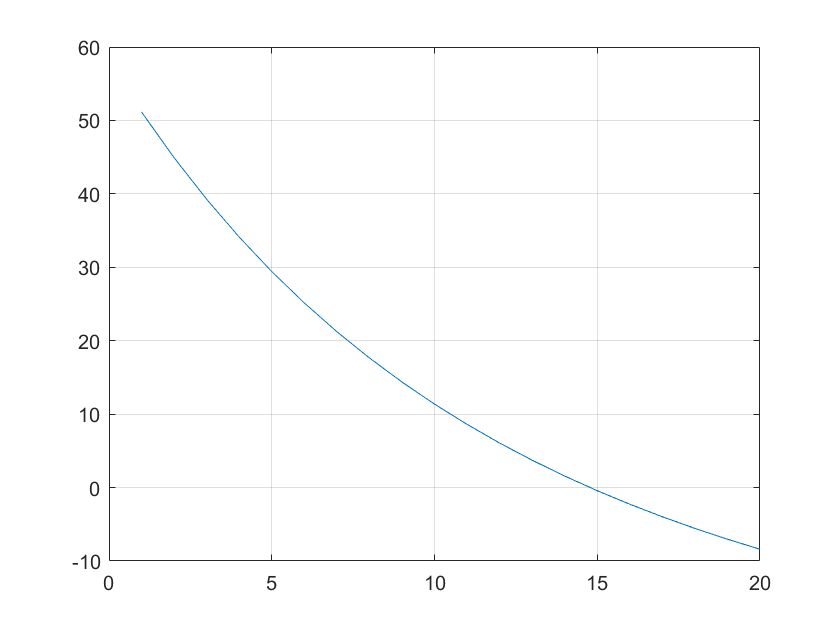

syms f c;
f(c) = (667.38/c)*(1 - exp(-0.146843*c))-40;
plot(1:20,f(1:20));grid on;

x_l = 4;
x_u = 20;

for i=1:10
    f_xl = f(x_l);
    f_xu = f(x_u);
    
    x_r = (x_l*f_xu - x_u*f_xl)/(f_xu - f_xl);
    
    f_xr = f(x_r);
    
    if f_xr < 0
        x_u = x_r;
        fprintf("xl");
    elseif f_xr > 0
        x_l = x_r;
        fprintf("xr");
    end
    
    fprintf('%f %f %f %f \n', f_xl, f_xu, x_r, f_xr);
end

xl

34.114889 -8.400624 16.838566 -3.709631 


xl

34.114889 -3.709631 15.579427 -1.510574 


xl

34.114889 -1.510574 15.088441 -0.593732 


xl

34.114889 -0.593732 14.898760 -0.230053 


xl

34.114889 -0.230053 14.825757 -0.088640 


xl

34.114889 -0.088640 14.797701 -0.034080 


xl

34.114889 -0.034080 14.786926 -0.013092 


xl

34.114889 -0.013092 14.782788 -0.005028 


xl

34.114889 

Error using fprintf
Unable to convert 'sym' value to 'double'.